# HMM Analysis

clear % clear all variables in the workspace
close all % close any figure windows that might be open
clc

addpath(genpath('./lib'))

## Part 1: Add working path and load the data

We will initialize the paths that are used later

% Make figure path
FigPath = ['./figure/'];
mkdir(FigPath)

Now, load all the data

load('./data/hmm_input_output.mat')

Specify some parameters

numParticle = length(hmm_input_output);
nc14 = 10;
TimeOffset = 2.5;
TimeSwitch = 20.3;

## Part 2: Fliter traces including quality control

First, we want to filter the traces based on SetID

dataID = 4; % We want to analyze "optoknirps_new_embryo10"
SetID_all = [hmm_input_output(:).SetID]; % SetID for all the traces
%TraceIndex = find(SetID_all == dataID); % Trace index that we will analyze

Then, we can assign the traces to each AP bin

APbinID = linspace(0,100,51);
APPosition_mean = zeros(numParticle,1);

for i = 1:numParticle
    APPosition_mean(i) = mean(hmm_input_output(i).APPosition);
end

APbinData = discretize(APPosition_mean,APbinID);

Quality control: Only keep the traces that is continuous across specified time range

QualityFlag = zeros(numParticle,1);

LeftBound = 15;
RightBound = 25;

for i = 1:numParticle
    MinTime = hmm_input_output(i).Time(1)/60-TimeOffset;
    MaxTime = hmm_input_output(i).Time(end)/60-TimeOffset;

    if (MinTime<LeftBound) && (MaxTime>RightBound)
        QualityFlag(i) = 1;
    else
        QualityFlag(i) = 0;
    end
end

## Part 3: Plot traces

Let's plot some traces

% Specify the bins we want to plot
binRange = 31:33; % 60%-64%
SpotTime = hmm_input_output(1).Time;
timeFactor = (SpotTime(2)-SpotTime(1))*60*5;

TraceIndex = find((SetID_all == dataID) & (ismember(APbinData,binRange)') & QualityFlag');

for i = TraceIndex
    ParticleID = hmm_input_output(i).ParticleID;
    SpotTime = hmm_input_output(i).Time/60-TimeOffset; % convert to min
    
    %{
    SpotFluo = hmm_input_output(i).SpotFluorescence;
    SpotViterbi = hmm_input_output(i).FluoViterbi;
    SpotInit = hmm_input_output(i).InitiationRate;
    PromState = hmm_input_output(i).PromoterState;
    
    TraceFig = figure;
    xlabel('Time into nc14 (min)')
    yyaxis left
    plot(SpotTime, SpotFluo,'- .','Color','#77AC30');
    hold on
    plot(SpotTime,SpotViterbi,'-m','LineWidth',1,'Color','#0072BD');
    yyaxis right
    stairs(SpotTime,PromState,'LineWidth',1.5,'Color','#D95319');
    %ylim([0 2.5])
    %}
    
    %{
    p = i;
    fluo_fig = figure;
    hold on
    plot(SpotTime,hmm_input_output(p).SpotFluorescence,'LineWidth',1.5)
    plot(SpotTime,hmm_input_output(p).FluoViterbi,'--','LineWidth',1.5)
    ylabel('spot fluorescence (au)')
    ylim([0 3E5])
    
    yyaxis right
    plot(SpotTime,hmm_input_output(p).NuclearKnirps,'-','Color','g','LineWidth',1.5)
    ylim([0 8E5])
    ylabel('knirps level (au)')
    
    xlabel('time into nc14 (min)')
    xlim([0 40])
    set(gca,'Fontsize',14)
    saveas(fluo_fig,[FigPath 'particle' num2str(ParticleID) '_fluo_plot.png'])
    
    v_fig = figure;
    hold on
    plot(SpotTime,hmm_input_output(p).InitiationRate,'LineWidth',1.5)
    stairs(SpotTime,hmm_input_output(p).PromoterState,'-','LineWidth',1.5)
    ylim([0 3E3])
    
    ylabel('initiation rate')
    yyaxis right
    plot(SpotTime,hmm_input_output(p).NuclearKnirps,'-','Color','g','LineWidth',1.5)
    ylim([0 8E5])
    ylabel('knirps level (au)')
    
    xlabel('time into nc14 (min)')
    xlim([0 40])
    set(gca,'Fontsize',14)
    saveas(v_fig,[FigPath 'particle' num2str(ParticleID) '_v_plot.png'])
    %}
end

## Part 4: Waiting-time distribution for purturbed region

We can use this to calculate response time

% Specify the bins we want to plot
binRange = 31:33; % 60%-64%
TraceIndex = find((SetID_all == dataID) & (ismember(APbinData,binRange)') & QualityFlag');

LaserOn = 20.3; % min
TimeOn = [];

%for i = 1:numParticle
for i = TraceIndex
    SpotTime = hmm_input_output(i).Time/60-TimeOffset; % convert to min
    PromState = hmm_input_output(i).PromoterState;
    [val,idx]=min(abs(SpotTime-LaserOn));
    
    if (PromState(idx) <10) && (val<2)
        temp_state = PromState(idx:end);
        temp_time = SpotTime(idx:end);
        frame_on = find(temp_state > 10, 1);
        time_first_on = temp_time(frame_on)-temp_time(1);
        TimeOn = [TimeOn time_first_on];
    end
end


Plot the distribution and exponential fitting

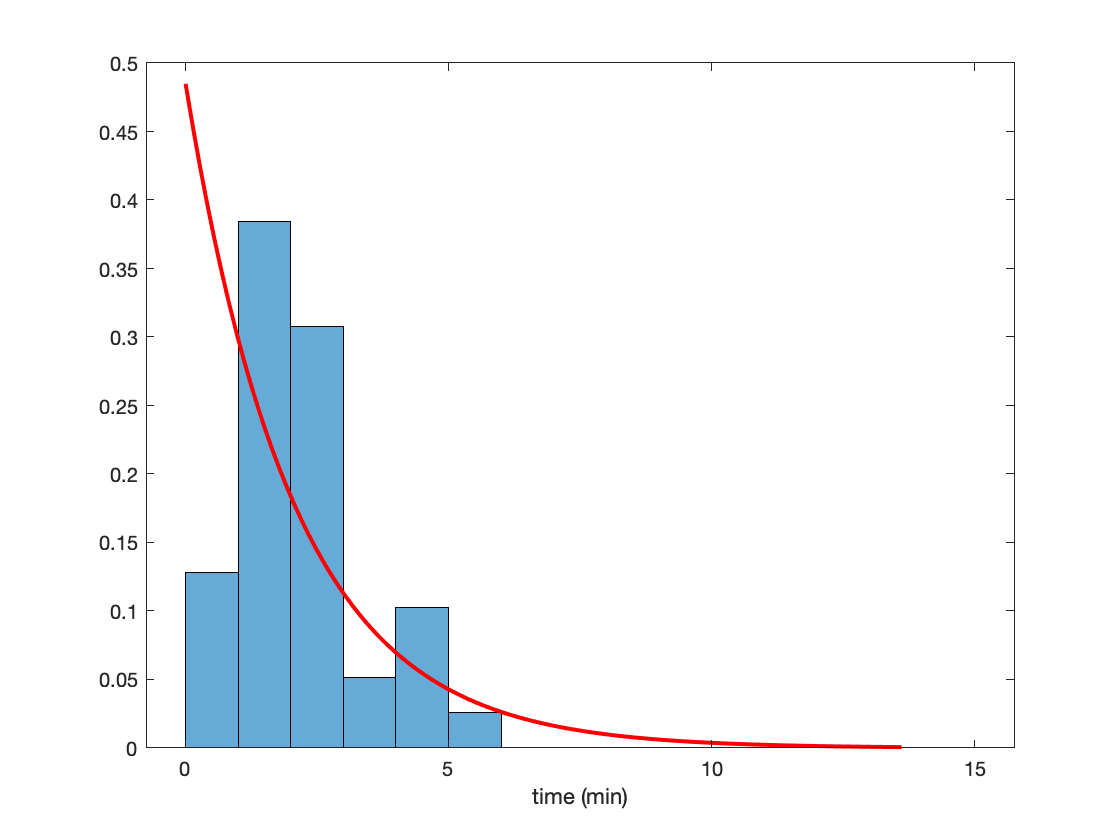

timeFigure = figure;

data = TimeOn;
dist = 'exponential';
pd = fitdist(data',dist);
% Find range for plotting
q = icdf(pd,[0.0013499 0.99865]); % three-sigma range for normal distribution
x = linspace(q(1),q(2));

% Do histogram calculations
edges = linspace(0,15,16);
h = histogram(data,edges,'Normalization','probability');
hold on
% Find range for plotting
q = icdf(pd,[0.0013499 0.99865]); % three-sigma range for normal distribution
x = linspace(q(1),q(2));

% Normalize the density to match the total area of the histogram
n = numel(data);
binwidth = edges(2)-edges(1); % Finds the width of each bin
area = n * binwidth;
y = area * pdf(pd,x);

% Overlay the density
hh1 = plot(x,y/n,'r-','LineWidth',2);

%histogram(TimeOn)
%histfit(TimeOn,5,'exponential')
xlabel('time (min)')

mean(data)

ans = 2.0598

SEM = std(data)/sqrt(length(data))

SEM = 0.1943

## Waiting time distribution for other areas???

First, we will try with stripe 7

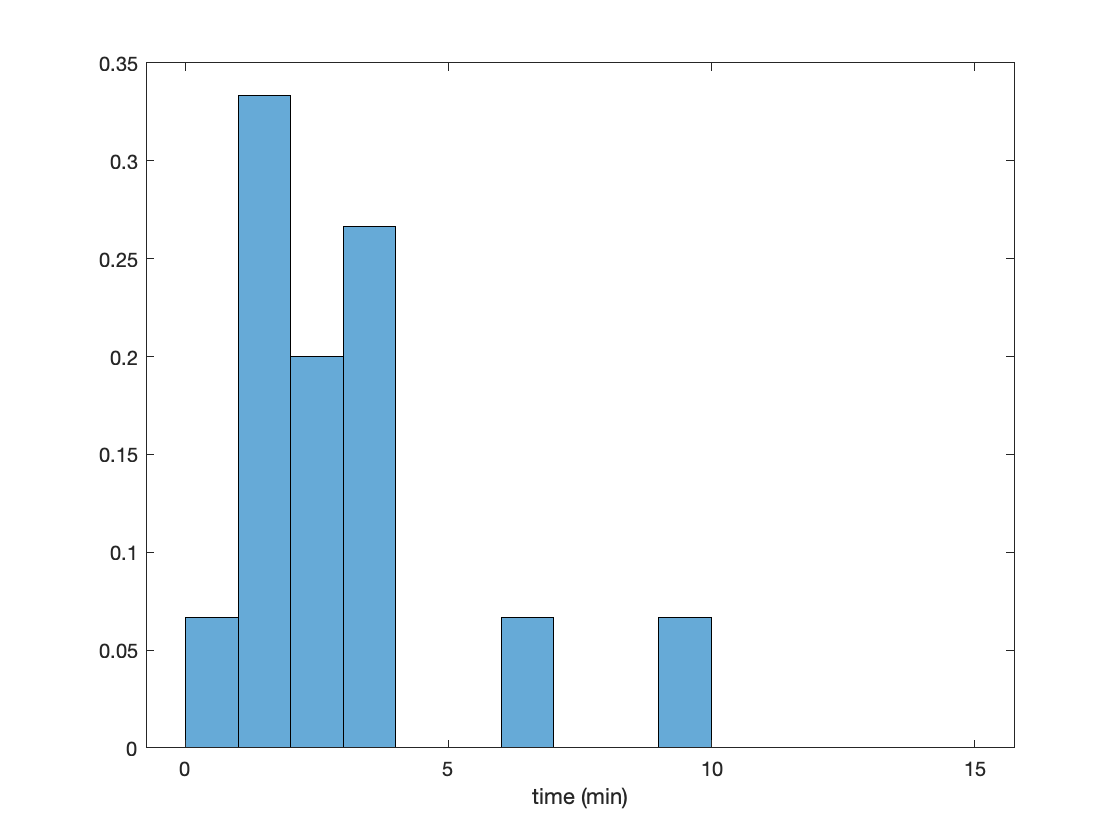

% Specify the bins we want to plot
binRange = 40:42; % 78-82%
%TraceIndex = find((SetID_all == dataID) & (ismember(APbinData,binRange)') & QualityFlag');
TraceIndex = find((SetID_all == dataID) & (ismember(APbinData,binRange)'));

LaserOn = 20.3; % min
TimeOn = [];

%for i = 1:numParticle
for i = TraceIndex
    SpotTime = hmm_input_output(i).Time/60-TimeOffset; % convert to min
    PromState = hmm_input_output(i).PromoterState;
    [val,idx]=min(abs(SpotTime-LaserOn));
    
    if (PromState(idx) <10) && (val<2)
        temp_state = PromState(idx:end);
        temp_time = SpotTime(idx:end);
        frame_on = find(temp_state > 10, 1);
        time_first_on = temp_time(frame_on)-temp_time(1);
        TimeOn = [TimeOn time_first_on];
    end
end

timeFigure = figure;
histogram(TimeOn,edges,'Normalization','probability')
%histogram(TimeOn,edges)
xlabel('time (min)')